clear all
clc

We must first add the folders themselves to MATLAB's current path in order to use the function contained in the following folders: "models", "data" and "utilities".

addpath("models");
addpath("data");
addpath("utilities");

**Load the cycle data **

This will allow to obtain informations about vehicle speed and acceleration as a function of time. 

mission = load("data\WLTP.mat");
time= mission.time_s;                   %(s)
vehSpd = mission.speed_km_h ./ 3.6;     %(m/s)
vehAcc = mission.acceleration_m_s2;     %(m/s^2)

**Plot the mission cycle**

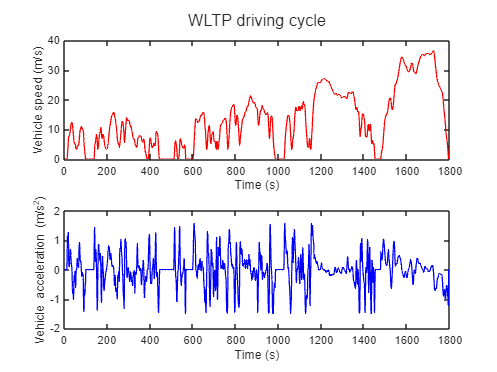

% Create the figure canvas
t=tiledlayout(2,1);

% Plot the speed as a function of time
nexttile(1)
plot(time, vehSpd, LineStyle="-", color="r", LineWidth=1);
xlabel("Time (s)");
ylabel("Vehicle speed (m/s)");
xlim([0, length(time)])

% Plot the acceleration as a function of time
nexttile(2)
plot(time, vehAcc, LineStyle="-", color="b", LineWidth=1);
xlabel("Time (s)");
ylabel("Vehicle acceleration (m/s^2)");
xlim([0, length(time)])

% Add a title
title(t, "WLTP driving cycle")

**Load the vehicle data**

veh = load("data\vehData.mat");

The scaling is done with respect to the motor and engine rated powers and the battery nominal energy.

This scaling is E-Machine and Engine maximum power in Watt followed by battery energy in Watt.Hour

veh = scaleVehData(veh, 64e3, 55e3, 1050);

**Note**

In order to navigate clearly and simply, the use of data_guide is very useful

**Set up our simulation loop**

initialize the state variable (SOC and engine state):

SOC(1) = 0.6 ;% -
engState(1) = 1; % engine on

for n = 1:length(time)
    [engSpd(n), engTrq(n)] = fuelControl(engState(n), vehSpd(n), vehAcc(n), veh); 
    [SOC(n+1), fuelFlwRate(n), unfeas(n), prof(n)] = hev_model(SOC(n), [engSpd(n), engTrq(n)], [vehSpd(n), vehAcc(n)], veh);
    engState(n+1) = engTrq(n) > 0;
end
prof = structArray2struct(prof);

fuelConsumption = sum(prof.fuelFlwRate).*1e-3;
dist = trapz(time, vehSpd)*1e-3;
fuelEconomy = fuelConsumption/veh.eng.fuelDensity/dist*1e2;
finalSOC = prof.battSOC(end);
fprintf("Fuel consumption: %.2f kg\n", fuelConsumption);

Fuel consumption: 2.01 kg


fprintf("Fuel economy: %.2f l/100km\n", fuelEconomy);

Fuel economy: 11.01 l/100km


% fprintf("Final SOC: %.3f \n", finalSOC);
save("optresults.mat", "prof", "fuelConsumption", "fuelEconomy", "finalSOC");